% Clear workspace and command window
clear;
clc;

% FOR DESKTOP: Read data from the Excel file
precip_data = readtable('One_Year_precip_EA011_May23_May24.csv');
SWC_data = readtable('One_Year_dSoilWC_EA011_May23_May24.csv');
drip_data = readtable ('Retime_NBC_Loggers_JANMAYdaily.csv');
water_budget = readtable('Copy_of_Rainfall_Loggers_PET_monthly_SUM.csv'); 

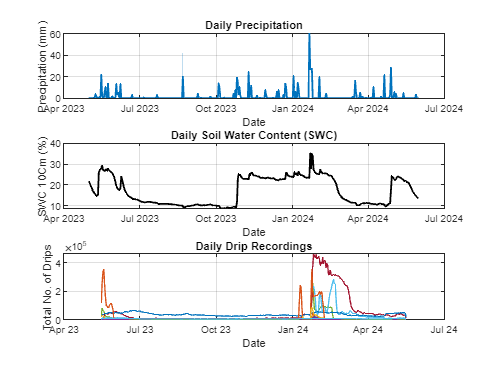


p_dates = precip_data {:, 1}; %Date is in column 1
rainfall = precip_data {:, 2}; %rainfall is in column 2

s_dates = SWC_data {:, 1}; %Date is in column 1
SWC= SWC_data {:, 2}; %rainfall is in column 2

d_dates = drip_data {:, 1}; %Date is in column 1
drip_count = drip_data{:, 2:21}; % Drip count is in columns 3 to 22

w_dates= water_budget {:, 1}; %Date is in column 1
p_et= water_budget{:, 4}; % P-ET is in columns 4



% Create a figure with 4 subplots in two columns
f= figure; clf

% Plot 1 in the first column, first row
subplot(3, 1, 1) % (3 rows, 2 columns, position 1)
plot(p_dates, rainfall,'LineWidth', 1.5); % Replace with your actual data
xlabel('Date');
ylabel('Precipitation (mm)');
title('Daily Precipitation');
grid on;

% Plot 2 in the first column, second row
subplot(3, 1, 2) % (3 rows, 2 columns, position 3)
plot(s_dates, SWC, 'k', 'LineWidth', 1.5); % Replace with your actual data
xlabel('Date');
ylabel('SWC 10Cm (%)');
title('Daily Soil Water Content (SWC)');
grid on;

% Plot 3 in the first column, third row
subplot(3, 1,3) % (3 rows, 2 columns, position 5)
for i = 1:size(drip_data)
    plot(d_dates, drip_count); % Replace with your actual data
    xlabel('Date');
    ylabel('Total No. of Drips');
    title('Daily Drip Recordings');
    grid on;
end

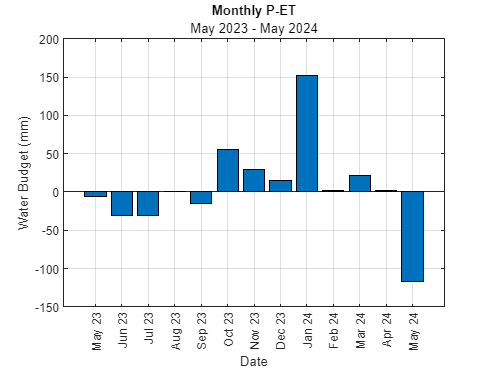


subplot
% Bar plot for the reduced subplot
bar((1:1:13), p_et, 'FaceColor', 'k'); % P-ET data plotted black
%bar((1:1:13), p_et); % P-ET data plotted blue
xlabel('Date');
ylabel('Water Budget (mm)');
title('Monthly P-ET', 'May 2023 - May 2024');
xtickangle(90);
xtick = {'May 23'; 'Jun 23'; 'Jul 23'; 'Aug 23'; 'Sep 23'; 'Oct 23'; 'Nov 23'; 'Dec 23'; 'Jan 24'; 'Feb 24'; 'Mar 24'; 'Apr 24'; 'May 24'};
set(gca, 'XTick', 1:1:13); % Set x-axis ticks at positions 1 through 13
set(gca, 'XTickLabel', xtick); % Set x-axis labels
grid on;

saveas(f, 'Chapman_Fig2_Layout.png');  % Saves the current figure as 'drip_count_plot.png' in the current directory
exportgraphics(f, 'Chapman_Fig2_Layout.png', 'Resolution', 1500);  % Saves the figure with 500 DPI resolution